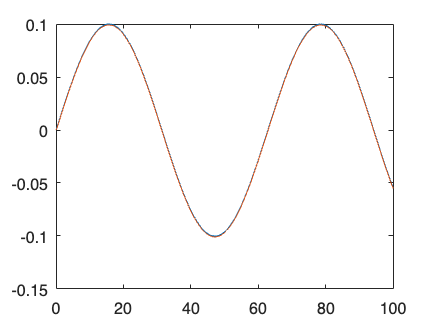

close, clear, clc

% Actual and erred params
m1 = 1; m2 = 1; l1 = 1; l2 = 1;
m1_ = 0.98 * m1; m2_ = 1.0 * m2; l1_ = l1 * 0.95; l2_ = l2 * 0.98;

% Anonymous functions for Mass Matrix, Non-linear, and Gravity terms
[M, C, G] = DOUBLE_PENDULUM_EOM(m1, m2, l1, l2);
[M_, C_, G_] = DOUBLE_PENDULUM_EOM(m1_, m2_, l1_, l2_);

% First order ODE form
f = @(x, u) [x(3:4); M(x(1:2)) \ (u - C(x(1:2), x(3:4)) * x(3:4) - G(x(1:2)))];

%% Initial conditions
x0 = [0; 0; 0.0; 0];

%% Desired trajectory
xd = @(t) [0.1*sin(0.1 * t); 0.3 * sin(0.2*t); 0.1 * 0.1 * cos(0.1 * t); 0.3 * 0.2 * cos(0.2 * t)];
xdd = @(t) [-0.1 * 0.1 * sin(0.1 * t); -0.3 * 0.04 * sin(0.2 * t)];

%% Kp and Kd from joint level LQR
k1 = 1226.5948; k2 = 280.4173;
% k1 = 7; k2 = 1;
K = [k1, 0, k2, 0; 0, k1, 0, k2];

%% ID controllers: 1) u_id: Actual Params 2) u_id_: Different params
u_id = @(x, t) M(x(1:2)) * (xdd(t) + K * (xd(t) - x)) + C(x(1:2), x(3:4)) * x(3:4) + G(x(1:2));
u_id_ = @(x, t, neta_) M_(x(1:2)) * (xdd(t) - neta_ + K * (xd(t) - x)) + C_(x(1:2), x(3:4)) * x(3:4) + G_(x(1:2));


%% Robust controller term calculation
A = [zeros(2,2),eye(2);-K];
B = [zeros(2,2); eye(2)];
Q = 1e1 * eye(4);
P = care(A, [], Q);
BTP = B' * P;
rho_ = 100;
eps = 1e-5;
r = @(x, t, rho) (norm(BTP * (xd(t) - x)) > eps) .* (-rho * BTP * (xd(t) - x) / norm(BTP * (xd(t) - x))) ...
          + (norm(BTP * (xd(t) - x)) <= eps) .* (-rho * BTP * (xd(t) - x) / eps);


%% Forward integration (Simulation)
% [t, y] = ode45(@(t, y) f(y, u_id_(y, t) + r(y, t)), [0 100], x0);

% H = zeros(100, 6);
H = zeros(0, 6);

dt = 1e-2; T = 50;
tspan=0:dt:T; t = tspan';
Y = zeros(length(tspan), 4);
NETA_ = zeros(length(tspan), 2);
NETA = zeros(length(tspan), 2);
condn1 = zeros(length(tspan)-1, 1);
V_dot = zeros(length(tspan)-1, 1);
condn2 = zeros(length(tspan)-1, 1);
condn3 = zeros(length(tspan)-1, 1);
% NETA(1, :) = [0, 0];
Y(1, :) = x0';
y_k = x0;
neta = zeros(1, 2);
rho = 0;
for k=1:length(tspan)-1
    tk = tspan(k);
    if (k > 1) && (mod(k, 1) == 0)
        [neta, rho] = uncertainty(y_k, H);
        NETA(k, :) = neta;
%         [neta, rho] = uncertainty([y_k; xdd(tk) + K * (xd(tk) - y_k)], H);
    end
    rho = min(rho, rho_);
    condn1(k, :) = norm(neta) - rho_;

    e = xd(tk) - y_k;
    w = BTP * (e);
    %% Checking different conditions for convergence
    V_dot(k) = -e' * Q * e + 2 * w' * (neta' + r(y_k, tk, rho));
    condn2(k) = norm(e) - sqrt(eps * rho_ / (2 * min(eigs(Q))));
    condn3(k) = min(eigs(A - (rho * B * BTP) / (norm(BTP * e))));

    %% forward integration
    y_kplus1 = rk4singlestep(@(t, y) f(y, u_id_(y, t, neta' - r(y, t, rho))), dt, tk, y_k);
%     y_kplus1 = rk4singlestep(@(t, y) f(y, u_id(y, t)), dt, tk, y_k);
    
    %% forming the input data
    qdd = (y_kplus1(3:4) - y_k(3:4)) / dt;
    a_cmd = xdd(tk) + K * (xd(tk) - y_kplus1);
    neta_k = qdd - a_cmd;

    %% check if the new point needs to be added
%     s = size(H);
%     len = s(1);
%     x = H(:, 1:4); y = H(:, 5:6);
%     xk = y_k;
% %     x = H(:, 1:6); y = H(:, 7:8);
%     kn = zeros(1, len);
%     Kn = zeros(len);
%     for i=1:len
%         kn(1, i) = kernel(xk, x(i, :)');
%     end
%     for i=1:len
%         for j=i:len
%             val = kernel(x(i, :)', x(j, :)');
%             Kn(i, j) = val;
%             Kn(j, i) = val;
%         end
%     end
% 
%     gamma = kernel(xk, xk) - kn * (Kn \ kn'); gamma

    if (mod(k, 10) == 0)
        H = [H; [y_kplus1', neta_k']];
%         H = [H; [y_kplus1', a_cmd', neta_k']];
        if length(H) > 50
            H = H(2:end, :);
        end
    end
    NETA_(k, :) = neta_k';
    Y(k + 1, :) = y_kplus1';
    y_k = y_kplus1;
end


%% Calculating the trajectory error
xd_ = xd(t')';
err = xd_ - Y;

%% Plotting and Visualization
plot(t, xd_(:, 1), t, Y(:, 1))

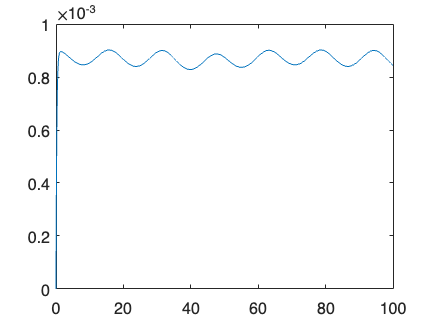

plot(t, err(:, 1))

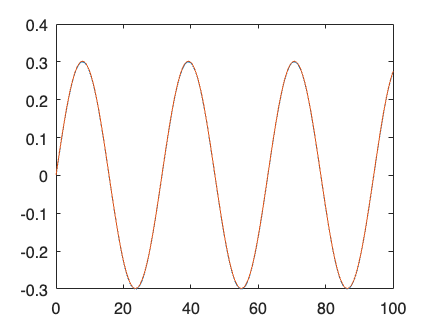

plot(t, xd_(:, 2), t, Y(:, 2))

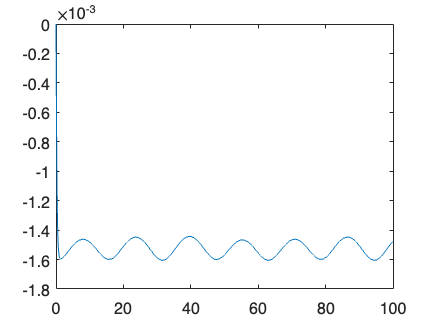

plot(t, err(:, 2))

% plot(condn1)
% plot(condn2)
% plot(V_dot)
% figure
% plot(t, y(:, 3), t, y(:, 4))